# Vector & Matrices

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-04-21

## Creating a Row and Column Vector

### Row vector

% row vector
row_vec1 = [1 2 3 4]; % sparated by space
row_vec2 = [1   2   3   4]; % separated by multiple spaces
row_vec3 = [1, 2, 3, 4]; % separated by commas
row_vec4 = 1:4; % use a colon operator
row_vec5 = [1:4]; % okay with putting square brackets

% they are identical
row_vec1
row_vec2
row_vec3
row_vec4
row_vec5

### Column vector

col_vec1 = [5;4;3];
col_vec2 = 5:-1:3; % not a column vector
col_vec3 = transpose(5:-1:3);
col_vec4 = col_vec2';

% col_vec1 is the same with col_vec3 and col_vec4
% col_vec1 is NOT the same with col_vec2
col_vec1
col_vec2
col_vec3
col_vec4

### Concatenation

vec = [1 2 3 7];
vec1 = [vec 8 7]; % adding elements
vec2 = [vec [8 7]]; % adding a row vector
vec3 = [vec [8;7]']; % adding a column vector after transposing
vec4 = [vec';8;7]';
% adding a column vector to the column vector (vec1') 
% and transpose an entire column vector
vec5 = vec;
vec5(5:6) = [8 7]; % valid code but not recomended

vec6 = cat(2, vec, [8 7]); % doc cat
% column: 1, row:2, depth: 3

% they are identical
vec1
vec2
vec3
vec4
vec5

### Modifying vectors

vec = [1 2 37];
vec
vec(1) = 5;
vec
vec(1:3) = [6 7 8];
vec
% vec(6) % error due to refer unassigned value

## Creating a Matrix

### Assinging values

mat1 = [1 2 3;4 5 6;7 8 9]; % direct assignment (concatenate rows)
mat2 = [1:3;4:6;7:9]; % use a colon operator
mat3 = [[1;4;7] [2;5;8] [3;6;9]]; % concatenate columns
mat4 = reshape(1:9, 3, 3)'; % will learn

% identical
mat1
mat2
mat3
mat4

### Use built-in functions to create matrices

mat1_0 = [0 0 0; 0 0 0; 0 0 0];
mat2_0 = zeros(3,3);
mat1_0
mat2_0

mat1_1 = [1 1 1; 1 1 1; 1 1 1];
mat2_1 = ones(3,3);
mat1_1
mat2_1

rand(3,3) % random matrix where its elements are real number within (0, 1)

mat1_random = randi([1 10], 3, 3); % random integer
mat1_random

% in general, it is receommend that matrices are created 
% using built-in functions because we can determine the size of the matrices 
% in beginning. 

mat1 = [1 2 3;4 5 6;7 8 9]; 

mat2 = zeros(3,3);
mat2(1,:) = [1 2 3];
mat2(2,:) = [4 5 6];
mat2(3,:) = [7 8 9];

% comment: if the size of matrices are large, the second method can avoid
% or easily detect a potential mistake.

### Matrix dimension

mat1 = rand(3,5);
[sc1, sr1] = size(mat1); % use 'size' function
n_elem1 = sc1 * sr1;

sc2 = size(mat1,1); % doc size 
sr2 = size(mat1,2); % 1 is a column, 2 is a row direction
n_elem2 = numel(mat1);

sc3 = numel(mat1(:,1)); % return a size of a column in mat1
sr3 = numel(mat1(1,:)); % return a size of a row in mat1
n_elem3 = numel(mat1); % return the total # of elements in mat1

% they are identical
[sc1 sc2 sc3]
[sr1 sr2 sr3]
[n_elem1 n_elem2 n_elem3]

### Modifying matrix

mat0 = zeros(5,5);
row_vec = 1:5;
col_vec = 6:10;
mat_sub = ones(2,3);

% initialize all mat# with mat0 (a 5x5 zero matrix)
mat01 = mat0; mat02 = mat0; mat03 = mat0; 
mat04 = mat0; mat05 = mat0; mat06 = mat0; 
mat07 = mat0; mat08 = mat0; mat09 = mat0; 
mat10 = mat0; 

% evaluate your resulting matrix
mat01(2,:) = row_vec;
mat02(:,3) = col_vec;
mat03(1:2,1:3) = mat_sub;
mat04(2:4,1:2) = mat_sub';
mat05(1:4,1) = col_vec(1:4);
mat06(1:4,1) = row_vec(1:4)';
mat07(2:end, 1) = col_vec(2:end);
mat08(2:end, end) = row_vec(2:end)';
mat09(1:4, 1:2) = 3;
mat10(1,:) = 5;

mat01
mat02
mat03
mat04
mat05
mat06
mat07
mat08
mat09
mat10



### Linear indexing

This is very important to understand how the matlab functions work. 

You should be used to convert a matrix to a linearly indexed vector and vice vercsa

% introduce 'reshape': doc reshape
vec0 = 1:10;
mat0 = reshape(vec0, 2, 5);
mat1 = reshape(vec0, 2, []); % same with mat0. 
% The second dimention is determined based on the # of element

% mat_error = reshape(vec0, 3,5); % error: dimension mismatch

mat0
mat1
clearvars vec0 mat0 mat1

% linear indexing
mat00 = zeros(4,4);
row_vec = 1:4;
col_vec = transpose(5:8);
mat_sub = [1 2 3;4 5 6];

% initialize all mat# with mat0 (a 5x5 zero matrix)
mat01 = mat00; mat02 = mat00; mat03 = mat00; 
mat04 = mat00; mat05 = mat00; mat06 = mat00; 
mat07 = mat00; mat08 = mat00; 

% You should understand how they work
mat01(1:4) = row_vec;
mat02(1:4) = col_vec;
mat03(1:5) = [col_vec; 10];
mat04(1:6) = mat_sub; 
mat05(1:6) = mat_sub'; 
% mat_error(1:7) =  mat_sub; % because of mismatching # of elements
mat06(8:11) = row_vec;
mat07([1 3 5 6]) = col_vec;
mat08([6 5 3 1]) = col_vec;

mat09 = reshape(1:16, 4, 4);
mat09(16:-1:1) = 1:16;

mat10 = reshape(1:16, 4, 4);
mat10(16:-1:1) = mat10(:); % this's cool!

mat01
mat02
mat03
mat04
mat05
mat06
mat07
mat08
mat09
mat10

### Empty vector

vec1 = 1:5;
vec1(end) = []; % remove the last element (become 1x4)
vec1(2) = []; % remove the second element (become 1x3)

% vec1(5) % errors

mat1 = reshape(1:16, 4, 4);
mat1(:,3) = []; % remove the 3rd column in 
mat1(2, :) = [];
% mat1(2, 1) = [] % error

vec1
mat1

### 3D matrix

% please think about what set of elements can be accessed using the
% following indexing
mat3D = reshape(1:120, 8, 5, 3);

mat3D(:,:,1)
mat3D(:,:,2)
mat3D(:,:,3)

mat1 = mat3D(:,1,1); 
mat2 = mat3D(1,1,:);
mat3 = mat3D(1,:,1);
mat4 = mat3D(2,:,:);
mat5 = mat3D(:,2,:);

mat1
mat2
mat3
mat4
mat5

### Scalar operations

mat1 = ones(3,3); 
mat2 = mat1 + 3; % add 3 to all elements in mat1
mat3 = mat1 + ones(3,3)*3; % it is the same with the above

mat4 = zeros(size(mat1));
mat4(:) = 4; % modify all elements to 4

mat2

mat2 =      4     4     4
     4     4     4
     4     4     4


mat3

mat3 =      4     4     4
     4     4     4
     4     4     4


mat4

mat4 =      4     4     4
     4     4     4
     4     4     4


### Array operations

matA = ones(3,3)*6;
matB = ones(3,3)*2;

mat1 = matA + matB; % matrix addition
mat2 = matB*4; % scalar multiplication
mat3 = matA - matB; % matrix subtraction
mat4 = matA.^2;  % array exponetial

matC = ones(4,4);
matC(1:2,1:2) = 2; % concatenation
macC(3:4,3:4) = 3;

matD = ones(4,4)*12;

mat5 = matC + matD;
mat6 = matC - matD; 
mat7 = matC.*matD; % array multiplication (element-wise multiplication)
mat8 = matD./matC; % array division (element-wise division)


matA

matA =      6     6     6
     6     6     6
     6     6     6


matB

matB =      2     2     2
     2     2     2
     2     2     2


matC

matC =      2     2     1     1
     2     2     1     1
     1     1     1     1
     1     1     1     1


matD

matD =     12    12    12    12
    12    12    12    12
    12    12    12    12
    12    12    12    12



mat1

mat1 =      8     8     8
     8     8     8
     8     8     8


mat2

mat2 =      8     8     8
     8     8     8
     8     8     8


mat3

mat3 =      4     4     4
     4     4     4
     4     4     4


mat4

mat4 =     36    36    36
    36    36    36
    36    36    36


mat5

mat5 =     14    14    13    13
    14    14    13    13
    13    13    13    13
    13    13    13    13


mat6

mat6 =    -10   -10   -11   -11
   -10   -10   -11   -11
   -11   -11   -11   -11
   -11   -11   -11   -11


mat7

mat7 =     24    24    12    12
    24    24    12    12
    12    12    12    12
    12    12    12    12


mat8

mat8 =      6     6    12    12
     6     6    12    12
    12    12    12    12
    12    12    12    12


## Logical Vectors and Operations

This is very important topics to write very efficient code and understanding the structure of the built-in functions

### Logical vectors

vec1 = 2:11;

logi_vec = ones(1,10, 'logical'); % all true 
logi_vec([3 5 7]) = false; % assign false logical values

vec2 = vec1(logi_vec); % access
vec3 = vec1(~logi_vec);

logi_equal_5 = (vec1==5);
vec4 = vec1(logi_equal_5);

logi_larger_5 = (vec1>5);
vec5 = vec1(logi_larger_5);

logi_smaller_5 = (vec1<5);
vec6 = vec1(logi_smaller_5);

mat1 = reshape(vec1, 2, 5);
vec7 = mat1(logi_equal_5);
vec8 = mat1(logi_larger_5);
vec9 = mat1(logi_smaller_5);

vec1

vec1 =      2     3     4     5     6     7     8     9    10    11


vec2

vec2 =      2     3     5     7     9    10    11


vec3

vec3 =      4     6     8


vec4

vec4 = 5

vec5

vec5 =      6     7     8     9    10    11


vec6

vec6 =      2     3     4


vec7

vec7 = 5

vec8

vec8 =      6     7     8     9    10    11


vec9

vec9 =      2     3     4


### Logical functions

How to check if there is a certain number in a vector? Let's say 5 in mat1. 

% Q:



### Elemenet-wise logical operations

Elemenet-wiose logical operations

### Matrix Multiplication

### Matrix times a vector

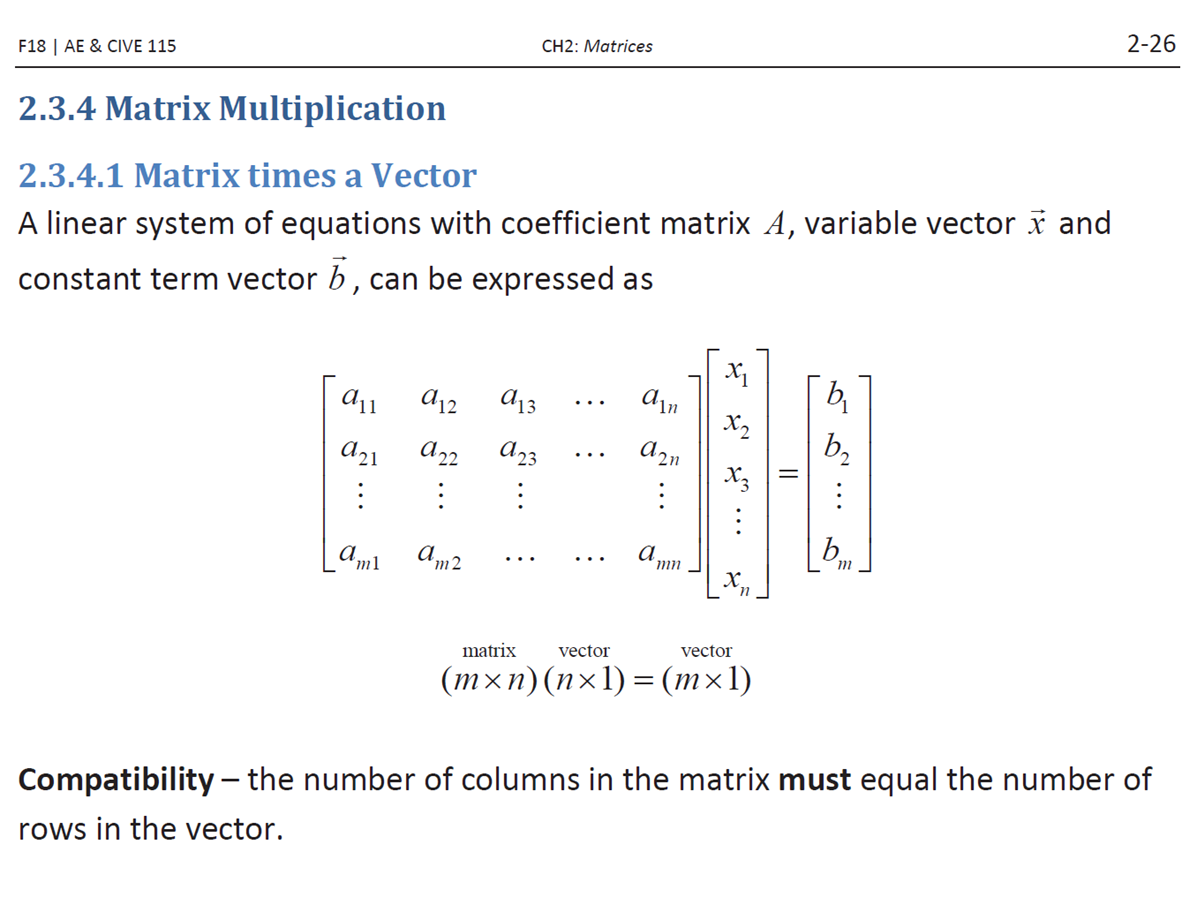

matA = reshape(1:9,3,3); 
vecA = [1;2;3];

vec1 = matA*vecA;

vec2 = zeros(3,1);
vec2(1) = matA(1,:)*vecA;
vec2(2) = matA(2,:)*vecA;
vec2(3) = matA(3,:)*vecA;

vec3 = zeros(3,1);
vec3(1) = sum(matA(1,:)'.*vecA);
vec3(2) = sum(matA(2,:)'.*vecA);
vec3(3) = sum(matA(3,:)'.*vecA);

vec4 = zeros(3,1);
vec4(1) = dot(matA(1,:)', vecA);
vec4(2) = dot(matA(2,:)', vecA);
vec4(3) = dot(matA(3,:)', vecA);

vec5 = sum(matA.*[vecA';vecA';vecA'],2);

% they are all identical.
vec1

vec1 =     30
    36
    42


vec2

vec2 =     30
    36
    42


vec3

vec3 =     30
    36
    42


vec4

vec4 =     30
    36
    42


vec5

vec5 =     30
    36
    42


(advanced topic) Let's understand above expression using symbolic experessions (will learn soon) 

clear;
syms a11 a12 a13 a21 a22 a23 a31 a32 a33
syms x1 x2 x3
A = [a11 a12 a13; a21 a22 a23; a31 a32 a33];
x = [x1;x2;x3];

vec1_syms = A*x;

vec2_syms(1,1) = A(1,:)*x;
vec2_syms(2,1) = A(2,:)*x;
vec2_syms(3,1) = A(3,:)*x;

vec3_syms(1,1) = sum(transpose(A(1,:)).*x);
vec3_syms(2,1) = sum(transpose(A(2,:)).*x);
vec3_syms(3,1) = sum(transpose(A(3,:)).*x);

vec5_syms = sum(A .* transpose([x x x]), 2);

vec1_syms

$$vec1\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$

vec2_syms

$$vec2\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$

vec3_syms

$$vec3\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$

vec5_syms

$$vec5\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$